# Deploy Line Detector and Following Controller as ROS Node

## Initialization

clear; close all; clc; rng('default');

## GPU code generation for line detector

### Test the function for code generation

fileName = 'trainVideo_2021_04_04_155139.avi';
videoReader = vision.VideoFileReader(fileName,'VideoOutputDataType','uint8');
videoPlayer = vision.DeployableVideoPlayer;
while ~isDone(videoReader)
    imdata = videoReader();
    Iocvin = mat2ocv(imdata);
    [predictedPosNorm,Iocvout]= line_detection(Iocvin);
    Iout = ocv2mat(Iocvout);
    videoPlayer(Iout);
end
figure
imshow(Iout);

### CUDA code generation

cfg = coder.gpuConfig('lib','ecoder',true);
cfg.GenCodeOnly = true;
cfg.TargetLang = 'C++';
cfg.GenerateReport = true;
cfg.ReportPotentialDifferences = false;
cfg.InitFltsAndDblsToZero = false;
cfg.BuildConfiguration = 'Faster Runs';
cfg.DeepLearningConfig = coder.DeepLearningConfig('cudnn');

% Only for Jetson targets
cfg.Hardware = coder.hardware('NVIDIA Jetson');
cfg.HardwareImplementation.TargetHWDeviceType = 'ARM Compatible->ARM 64-bit (LP64)';

arg = coder.typeof(uint8(0), [3 1280 720], [0 1 1]);
codegen -config cfg line_detection -args {arg} -report

% Packing the required files to be sent to the target
load(fullfile('codegen','lib','line_detection','buildInfo'));
packNGo(buildInfo,{'packType', 'flat', ...
    'fileName','line_detection'});

### Stop all ROS nodes on JetBot

stopJetBotROSNode;

### Generate CUDA code and transfer it to JetBot to be built

Set up the IP address, user name and password to connect to the Jetson

% Jetson's IP address, user name, password
load('jetsonIpAddr');
d = rosdevice(jetsonIpAddr,'jetbot','jetbot');
d.ROSFolder = '/opt/ros/melodic';
d.CatkinWorkspace = '~/workspace/catkin_ws';

Compress the all required files and transfer the archive to the JetBot through SSH

proj = currentProject; rootfolder = proj.RootFolder;
zip('line_detector.zip','line_detector',fullfile(rootfolder,'src','007_hardware_deployment'));
d.putFile('line_detector.zip',d.CatkinWorkspace);
d.system(['rm -fr ',d.CatkinWorkspace,'/src/line_detector']);
d.system(['unzip ',d.CatkinWorkspace,'/line_detector.zip -d ',d.CatkinWorkspace,'/src/']);
d.putFile('line_detection.zip',d.CatkinWorkspace);
d.system(['unzip ',d.CatkinWorkspace,'/line_detection.zip -d ',d.CatkinWorkspace,'/src/line_detector/src/codegen']);
d.system(['touch ',d.CatkinWorkspace,'/src/*/*/*']);

Open the shell and type the following commands to build the ROS node.

d.system(['cd ~/workspace/catkin_ws;source /opt/ros/melodic/setup.bash ;catkin_make']);
%d.openShell;

#### Test the deployed line detector ROS node

Feed images from MATLAB to the line detector ROS node on the Jetson and see the results. (/line_detector is the deployed ROS node below)

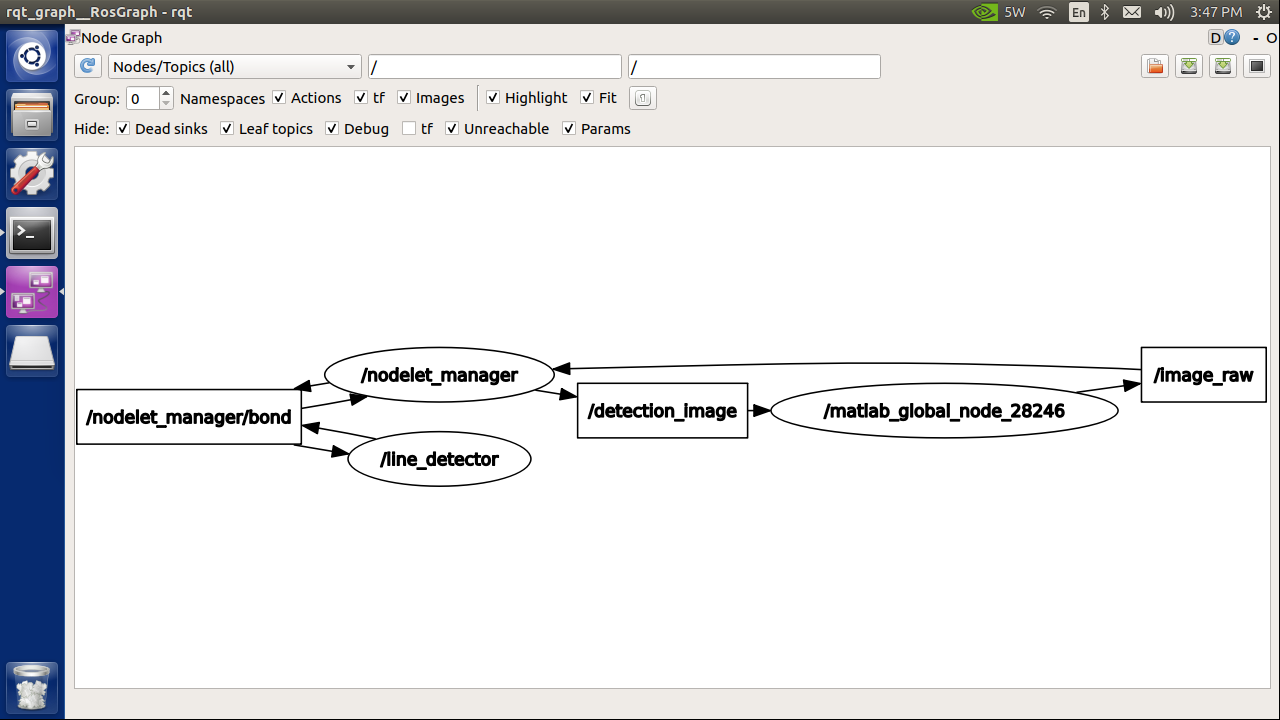

videoFReader = vision.VideoFileReader(fileName,'VideoOutputDataType','uint8');
rosshutdown;
rosinit(jetsonIpAddr);
depVideoPlayer = vision.DeployableVideoPlayer;
detImgSub = rossubscriber('/detection_image');
[imgPub,imgMsg] = rospublisher('/image_raw');
imgMsg.Encoding = 'rgb8';
cont = ~isDone(videoFReader);
while cont
    % Read an image
    I = step(videoFReader);

    % Publishe the image to the line detector node
    imgMsg.writeImage(I)
    send(imgPub,imgMsg);
    
    % Receive the result and visuzalize it
    mymsg = receive(detImgSub);
    out = readImage(mymsg);
    step(depVideoPlayer, out);
    cont = ~isDone(videoFReader) && isOpen(depVideoPlayer); % Exit the loop if the video player figure window is closed
end
figure;
imshow(out);

## Deploy line follower Simulink model as ROS node

### Launch the deployed line detector node with a camera driver node

d.openShell;

### Check the detection results

rosshutdown;
rosinit(jetsonIpAddr);
videoPlayer = vision.DeployableVideoPlayer;
camSub = rossubscriber('/detection_image', @(event,msg) videoPlayer(readImage(msg)));

### Check the following controller Simulink model

open_system('ros_line_follower');

1. Select "ROS Network" in the "SIMULATION" tab.

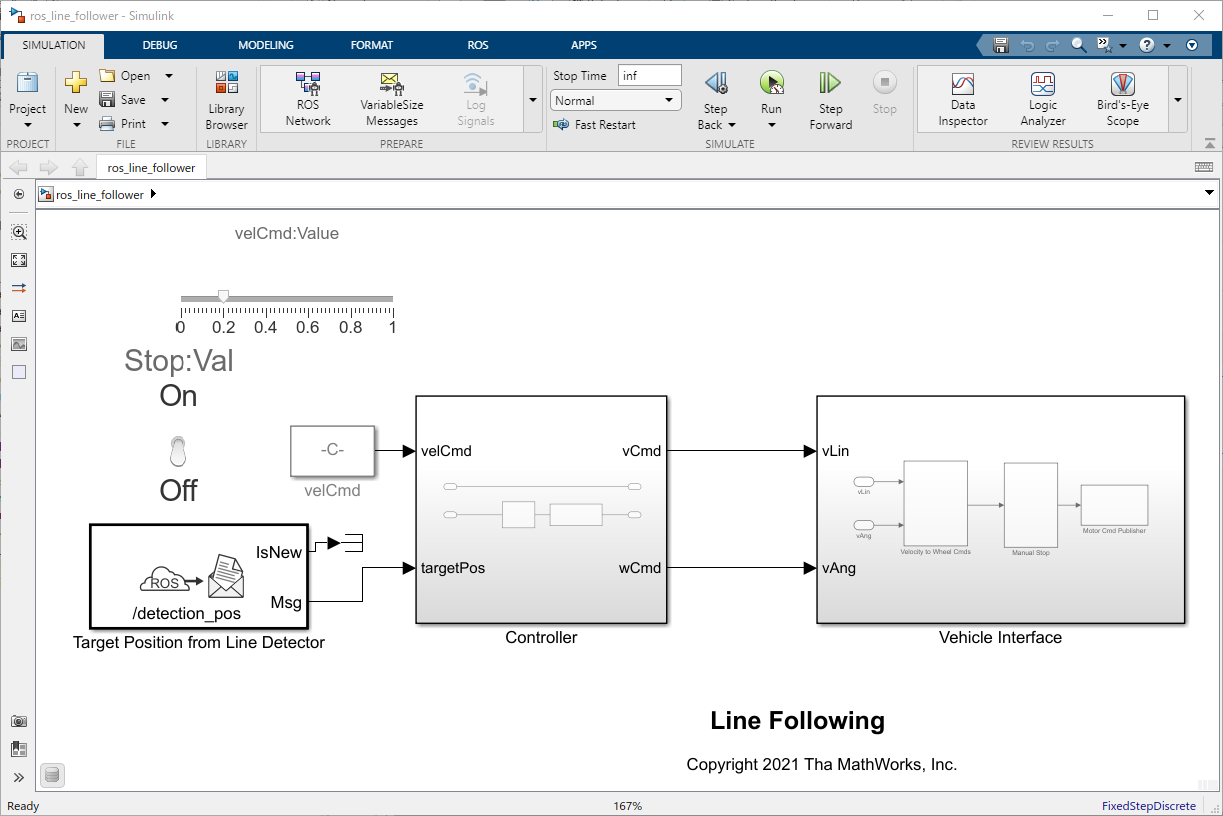

2. Set "Network Address" to "Custom", "Hostname/IP Address" to the JetBot(Jetson Nano)'s respectively.

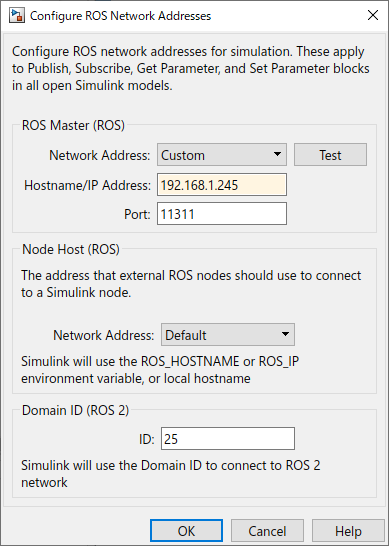

3. Run the simulation by clicking the green triangle button in the "SIMULATION" tab and see the JetBot is following the line.

ROS network graph should be something like below (Red ellipse is the Simulink model)

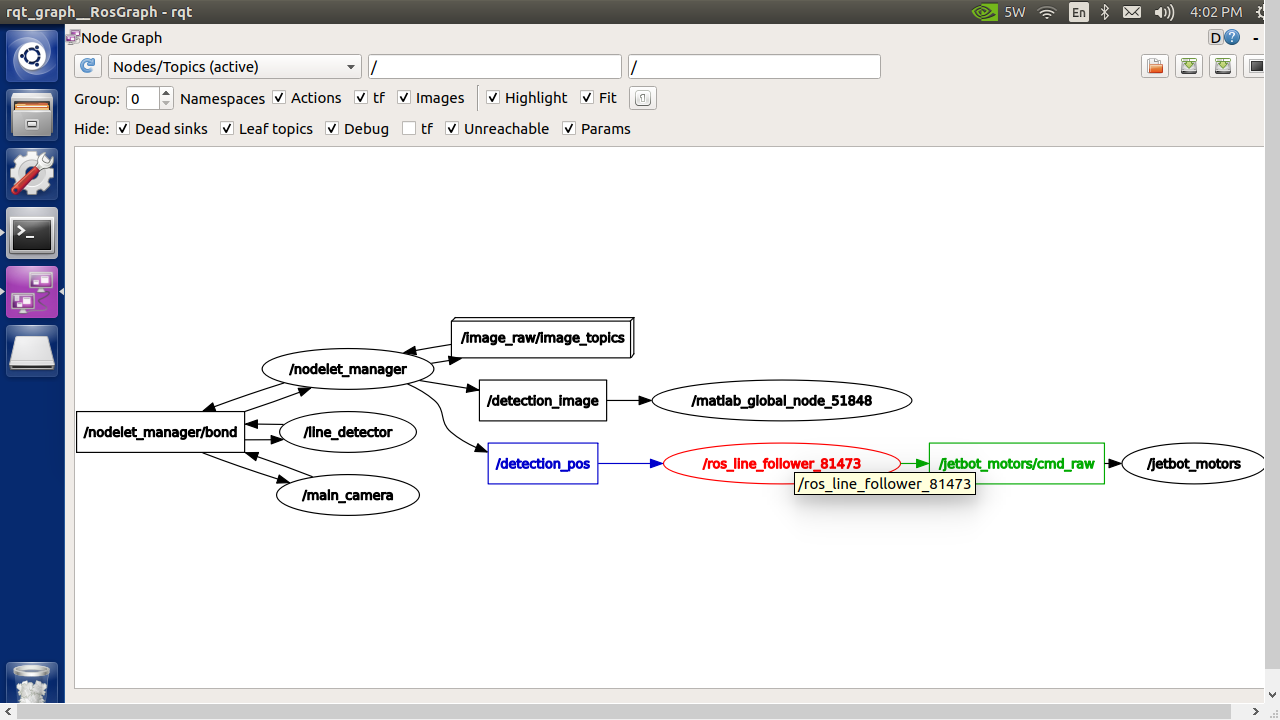

### Deploy the Simulink model as ROS node

1.Select "Manage Remote Device" in the "Deploy to" group in the "ROS" tab.

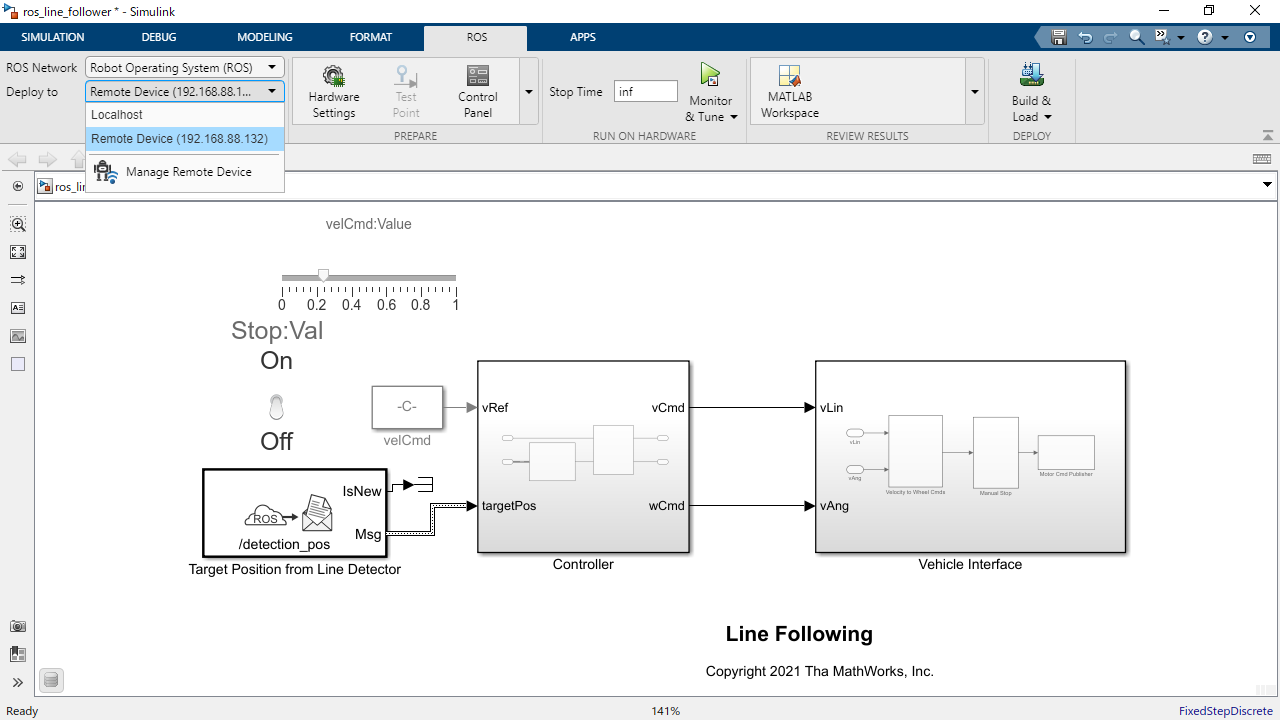

2. Specify the IP address, username, password respectively. In addition, the catkin workspace should be like below.

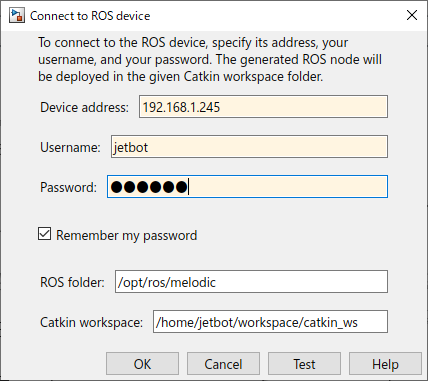

3.Run roscore on the JetBot

d.openShell;

4.Click "Build & Load" in the "ROS" tab to generate ROS node and built it with catkin on the target.

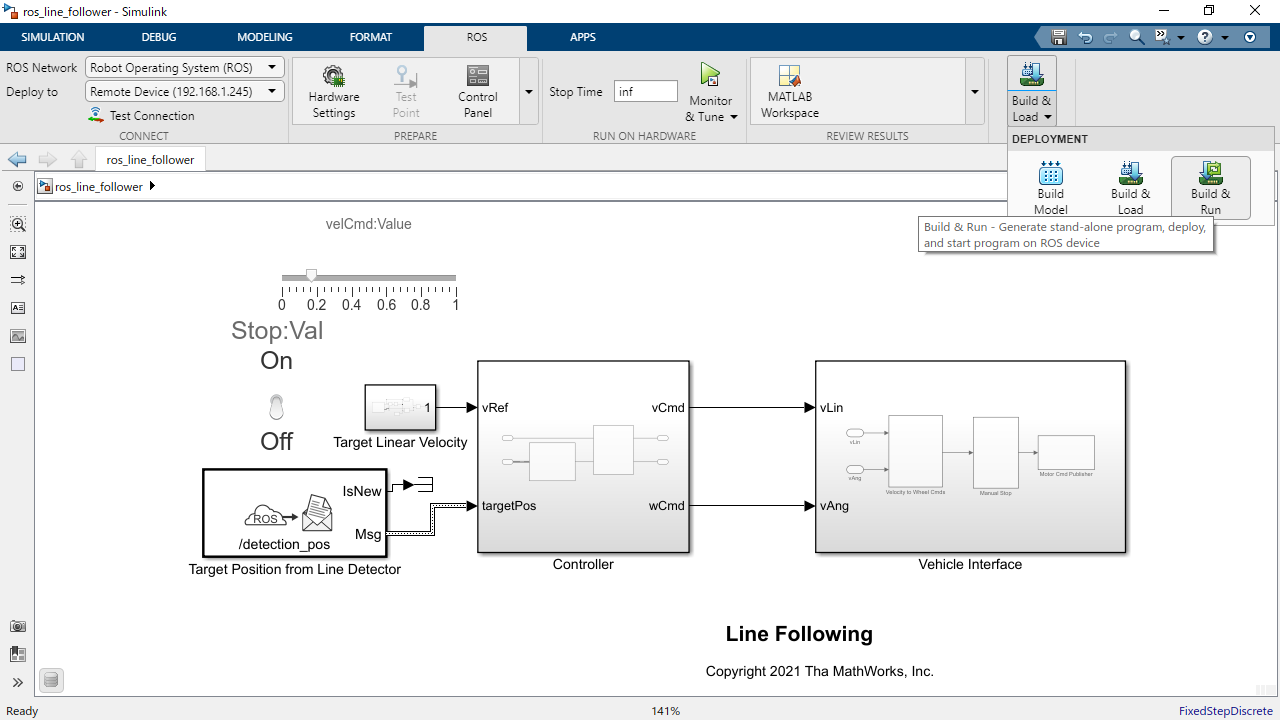

## Standalone ROS node execution

Now, all functionalities for line detection and following are deployed as ROS node. We will control the target velocity and the start/stop operation from another Simulink model.

1. Launch all the deployed ROS nodes

d.openShell;

2. Open a monitor Simulink model

open_system('ros_monitor'); 

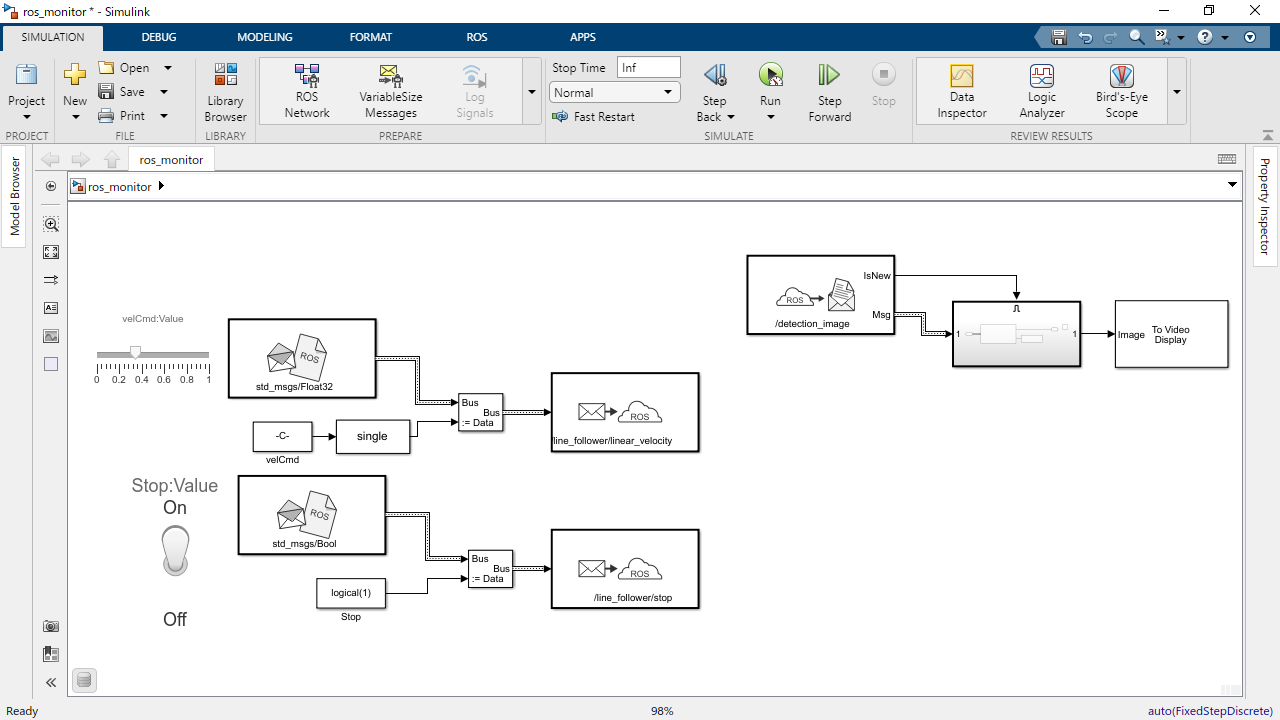

3. Run the monitor Simulink model and deactivate the "Stop" toggle button to start the line following.

ROS node graph during the execution.

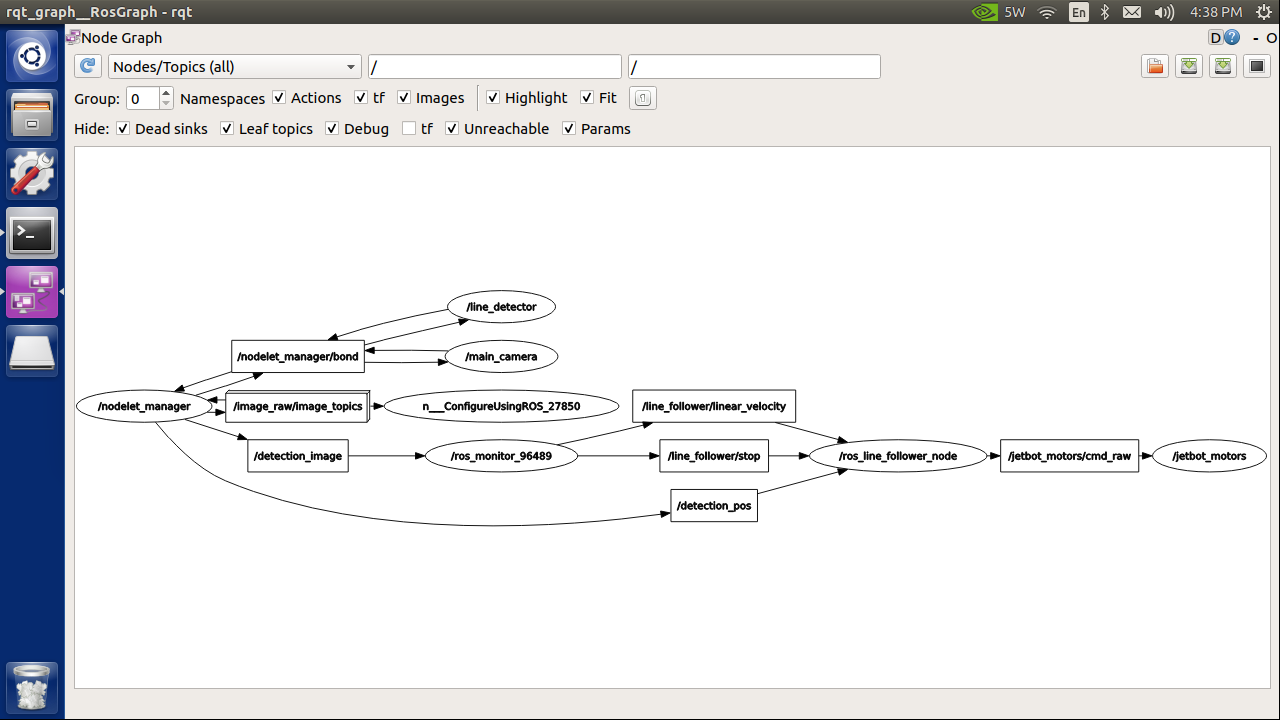

*Copyright 2021 The MathWorks, Inc.*